% GPIB Test Suite
% Uwe Rother
% this one uses visadev instead of gpib
% as gpib seems to become outdated in matlab
%
% 04.01.2025
%
% HP4192A is a little bit sticky to programm
% sometimes it takes long to answer
%
% findings:
% - when sweep is set to Auto, then Range is also automatically switched to
%   auto!
% - it seems, responsetime depends on B display calculation?
% - Ref calibration shoud be:
%   1) 
%   2)

clc;
close all;
clearvars -except runcounter measData
delete(visadevfind());

### Manage some persistent variables

for comparison of ongoing measurements

if exist('runcounter') == 1
    runcounter = runcounter + 1;
else
    runcounter = 1;
    measData = {};
end

titleString = 'L&B-Spule';

% Unterordner "Messungen" erstellen, falls nicht vorhanden
messFolderName = 'Messungen';
if ~exist(messFolderName, 'dir')
    mkdir(messFolderName);
end

% Unterordner "Messungen" erstellen, falls nicht vorhanden
pngFolderName = 'Graphs';
if ~exist(pngFolderName, 'dir')
    mkdir(pngFolderName);
end

### Init of HP4192A

% use of short name "d" for HP4192a device
d = visadev("GPIB0::1::INSTR");
pause(4);
% d.EOIMode = "off";
d.Timeout = 1;

### Setup HP4192A for this measurement

#### Stop generating SRQ

%first switch of any SRQ gen sources
writeline(d,'D0');      %Data Ready off
writeline(d,'T2');      %Trigger ext

%read and dismis status byte
[tf,statusByte] = visastatus(d);

#### Configure Type of Measurement (Z, L, C...)

writeline(d, 'A3B3');       % L / R
writeline(d, 'F1');         % Display A/B/C
labelLeftY = 'L in H';
labelRightY = 'R in Ohm';

#### Set Start-, Stop-, Step- and Spot Frequencies

% Frequenzparameter setzen (in Hz)
startFreq = 100;
stopFreq  = 500000;
stepFreq  = 2000;

f_Hz = transpose(startFreq:stepFreq:stopFreq);
f_kHz = (f_Hz ./ 1000);
[l,~] = size(f_kHz);
L = zeros(l,1);
Q = zeros(l,1);
sweep = struct('f',f_kHz,'L',L,'Q',Q);
sweep.f = f_kHz;

strSpotFreq = sprintf('FR%09.4fEN',startFreq/1000);
strStartFreq = sprintf('TF%09.4fEN',startFreq/1000);
strStopFreq = sprintf('PF%09.4fEN',stopFreq/1000);
strStepFreq = sprintf('SF%09.4fEN',stepFreq/1000);

writeline(d, strSpotFreq);       % Spot Freq
writeline(d, strStartFreq);       % Startfrequenz: 1 kHz
writeline(d, strStopFreq);       % Stopfrequenz: 1 MHz
writeline(d, strStepFreq);        % Schrittweite: 10 kHz

#### Use Manual Sweep with SRQ on Data Ready

writeline(d,'W0');                % sweep Man
writeline(d,'D1');                % Data Ready on

%clear status, just in case
statusByte = 255;
[tf,statusByte] = visastatus(d);
if tf
    disp(['found non empty status: ',dec2hex(statusByte)]);
else
    %disp('Status empty')
end


#### Prepare Measurement

% Grafik erstellen
h= figure;
title(titleString);
grid on;
hold on;
set(gcf,'Visible','on');
yyaxis left;
p1 = plot(sweep.f,sweep.L,'XDataSource','sweep.f','YDataSource','sweep.L');
xlabel('f/kHz');
ylabel(labelLeftY);
%ylim([5e-06 10e-06]);
yyaxis right;
p2 = plot(sweep.f,sweep.Q,'XDataSource','sweep.f','YDataSource','sweep.Q');
ylabel(labelRightY);
linkdata on;

xlim([f_kHz(1) f_kHz(end)]);
% ylim([-1 5]);

#### Start Manual Sweep

writeline(d,'W2');  %start sweep
writeline(d,'R8');  %Range (only valid without auto sweep)

#### Loop for each frequency in f_kHz

for j=1:l
    %disp('----------');
    %disp('Trigger');
    d.visatrigger();    %equal to writeline(d,'EX')
    pause(0.1000);

    while true  %wait until data ready in status
        %disp('check statusbyte');
        statusByte = 255;
        [tf,statusByte] = visastatus(d);
        %pause(0.1);
        %disp(['Status: ',dec2hex(statusByte)]);
        measReady = bitget(statusByte,1,"uint8");
        if measReady
            %disp('data ready');
            break;
        else
            %disp('wait for data ready');
        end      
    end
    y = readline(d).split;
    A = str2double(extractAfter(y(1),4));
    B = str2double(extractAfter(y(2),4));
    C = str2double(extractAfter(y(3),4));
    %disp(A);
    %disp(B);
    %disp(C);
    sweep.L(j) = A;
    sweep.Q(j) = B;
    %sweep.dispC = C;
    refreshdata(p1);
    refreshdata(p2);
    % next sweep manual step
    writeline(d,'W2');
end

% add this sweep to collection of all sweeps in a cell array
measData{runcounter} = sweep;

#### Add previous measurement for comparison (if exists)

% if there is a previous measurement add it to the current figure
if(runcounter > 1)
    try
        lastplot = measData{runcounter-1};
        yyaxis left;
        plot(lastplot.f,lastplot.L);
        yyaxis right;
        plot(lastplot.f,lastplot.Q);
    catch
        disp('no previous measurement')
    end
end

%finally clear any SRQ request flag
visastatus(d);

#### Save figure file

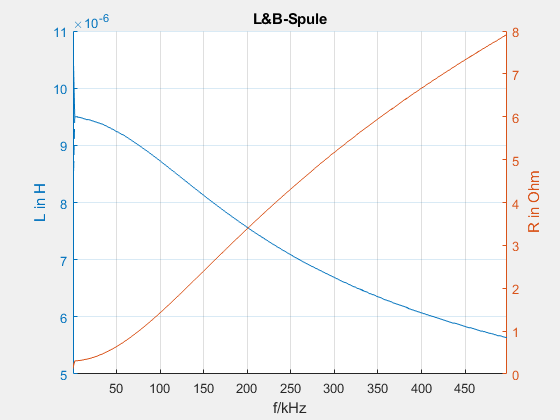

% Aktuelles Datum im Format YYYY-MM-DD
datum = datestr(now, 'yyyy-mm-dd');

% save figure to file
figdateiname = sprintf('%s/Figure_%s_%d.png', pngFolderName, datum, runcounter);
saveas(gcf,figdateiname);

#### Save data to csv file

% Dateiname generieren
dateiname = sprintf('%s/Messung_%s_%d.csv', messFolderName, datum, runcounter);

% Headerzeile für csv definieren
header = 'Frequency (Hz); Magnitude (Ohms); Phase (Degrees)';

% Datei öffnen
fileID = fopen(dateiname, 'w');  % Datei zum Schreiben öffnen

% Header schreiben
fprintf(fileID, '%s\n', header);

% Daten Zeile für Zeile schreiben
for i = 1:l
    fprintf(fileID, '%.4e;%.4e;%.4e\n', sweep.f(i), sweep.L(i), sweep.Q(i));
end

% Datei schließen
fclose(fileID);

#### ave data to xlsx file

% Dateiname generieren
dateiname = sprintf('%s/Messung_%s_%d.xlsx', messFolderName, datum, runcounter);

% Headerzeile für csv definieren
header = {'f in kHz', 'L in H', 'R in Ohm'};
dataMatrix = [ sweep.f(:), sweep.L(:), sweep.Q(:)]; % Spaltenweise Anordnung
dataTable = [header; num2cell(dataMatrix)]; % Kombiniere Header mit Daten

% Schreiben in eine Excel-Datei
writecell(dataTable, dateiname);

#### cleanup

%disp(['Datei gespeichert: ', dateiname]);
clearvars -except runcounter measData
disp('thank you for running this skript');

thank you for running this skript
